# Part_A.mlx

Generate a test signal

Fs = 1024;               % Sampling frequency
t = -0.5:1/Fs:0.5-1/Fs;  % Time vector
f = pi;                  % Frequency of the signal
x = sin(2*pi*f*t);       % Test signal (sine wave)

N = length(x);
f_axis = (-N/2:N/2-1) * (Fs/N);

Compute the FFT

X = fft_dft(x);

Display the original signal & the single-sided amplitude spectrum

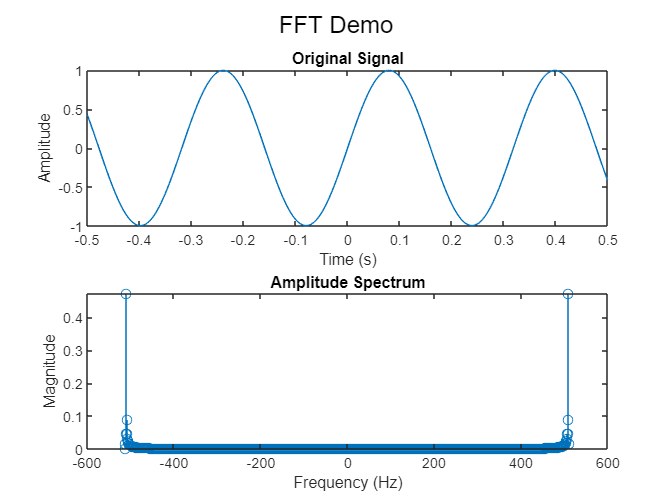

subplot(2, 1, 1);
plot(t, x);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
stem(f_axis, abs(X/N));
title('Amplitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

sgtitle('FFT Demo');

Perform the inverse FFT

x_inv = ifft_dft(X);

Plot the real part of the IFFT

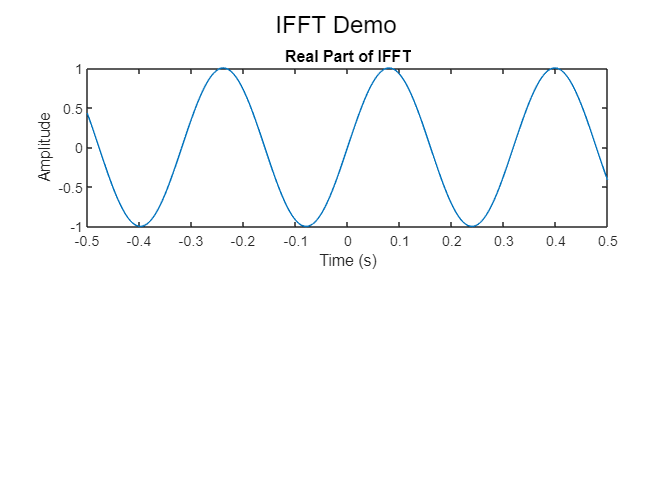

t_inv = -0.5:1/Fs:0.5-1/Fs;

figure;
subplot(2, 1, 1);
plot(t_inv, real(x_inv));
title('Real Part of IFFT');
xlabel('Time (s)');
ylabel('Amplitude');

sgtitle('IFFT Demo');